# Spacecraft Dynamics and Attitude Control

This example shows how to build an attitude controller for a spacecraft in Simulink. The example points the spacecraft at the sun throughout the orbit by first determining the shortest quaternion rotation required, using PID Control blocks to determine the required moments on the spacecraft, and propagating the spacecraft's new dynamics. This example is an illustration of the capabilities of the Aerospace Blockset.

This example uses the "prelim_ex_3_simulink.slx" model, which already contains an “Altitude Controller” subsystem. To complete the subsystem, we will determine the required quaternion rotation and propagate the dynamics of the spacecraft. 

## Define Orbital Parameters

For this example, we will use the same orbit parameters as the previous exercise. These parameters are defined in the code below. They are stored in the workspace and will be used by the Simulink model we design.

% Define Keplerian Orbital Elements
semiMajorAxis = 1e7;               % meters
eccentricity = 0.2;
inclination = 0;                   % degrees
rightAscensionOfAscendingNode = 0; % degrees
argumentOfPeriapsis = 0;           % degrees
trueAnomaly = 0;                   % degrees


% Define a start time of the 19th August, 2020, at 8:55 PM UTC. Using the
% datetime function
startTime = datetime(2020,8,19,20,55,0);


Convert the specified "startTime" to a Julian date. Use the "juliandate" function.

Hint: To learn more about the "juliandate" function, type "doc juliandate" in the command window.


% Convert the start time into julian data. Use the juliandate function
%[ADD CODE HERE]



## Open the Model

Double click "Work_Exercise3_SimulinkModel.slx".

open_system("Work_Exercise3_SimulinkModel.slx");

## Determine the Required Quaternion Rotation

To calculate the shortest quaternion rotation required to point the spacecraft at the sun, add the "Attitude Profile (Sun Tracking)" block in the designated area in the model.

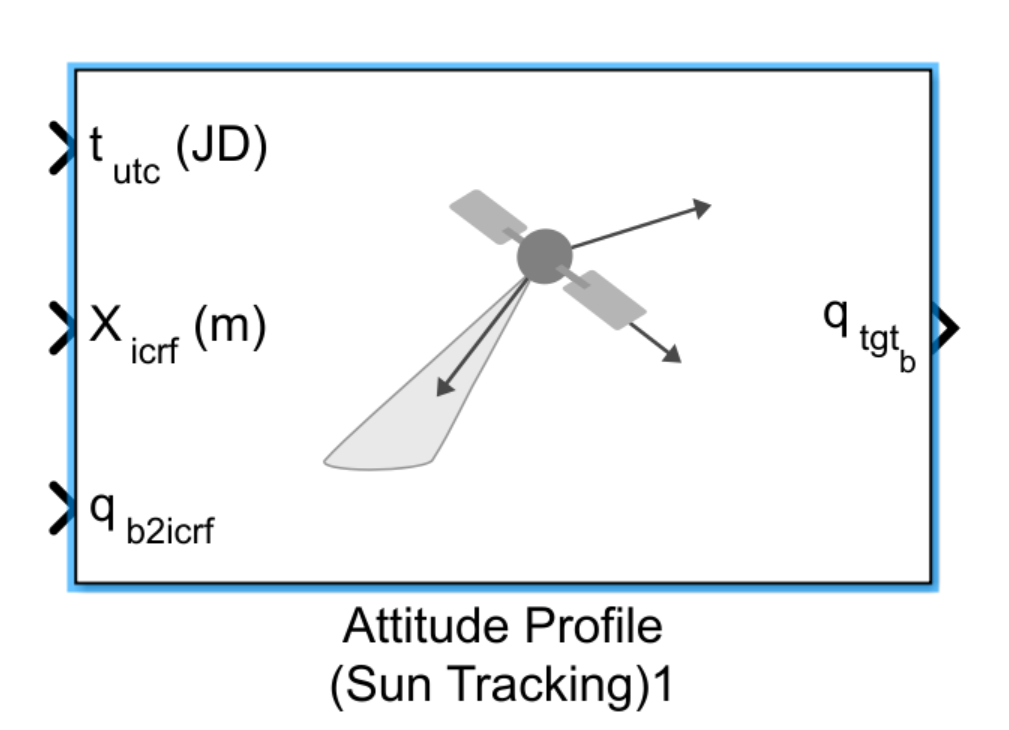

Double-click the block to access its block parameters. Ensure that the "Port coordinate frame" is set to ICRF (the International Celestial Reference Frame), the "Pointing mode" is set to "Point at celestial body", and the "Celestial target" is set to "Sun".

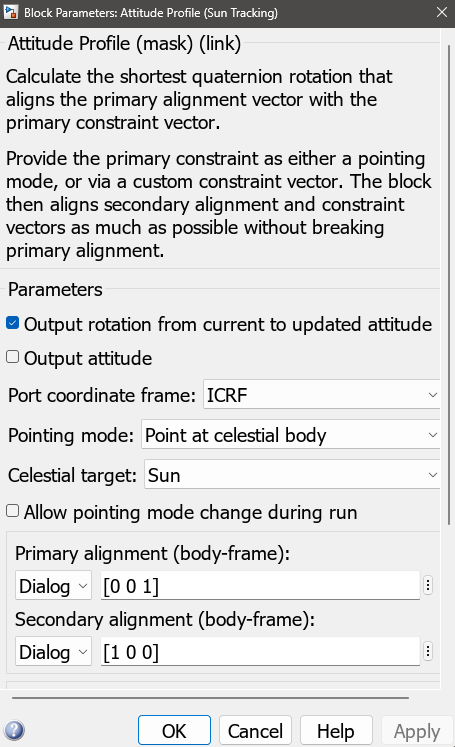

Note that the block requires inputs of Universal Coordinated Time (in Julian Date), spacecraft positions in the International Celestial Reference Frame, and the quaternion relating the spacecraft's current attitude with respect to the International Celestial Reference Frame. We will discover how to compute these later.

## Convert Quaternions to Rotation Angles and Implement Attitude Control

Click within the "Attitude Controller" subsystem. To determine the moments that need to be provided to the spacecraft to reach the desired attitude we use PID Control. 

For computational convenience, convert the quaternions to rotation angles to feed them to the three PID Controller Blocks. Use the "Quaternions to Rotation Angles" block.

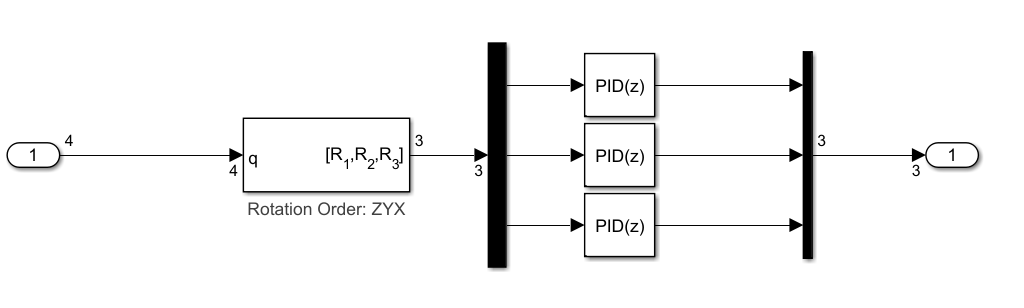

For more information about the block's functionality, right-click on it and select "Help".

Now, double-click the block and set the Rotation Order to be "XYZ":

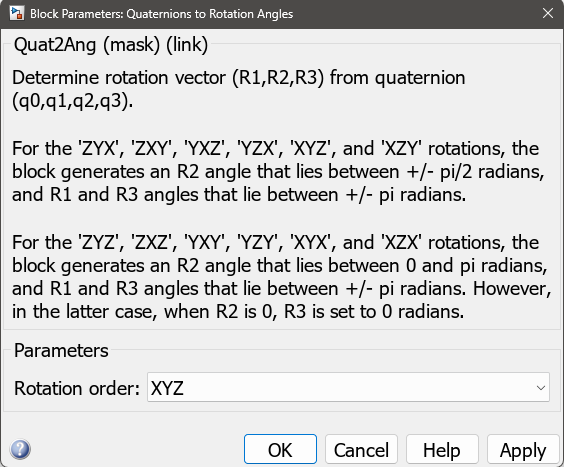

Click "OK", and click back to the top level model.

Note that the output of the "Attitude Controller" subsystem now contains the moments to be applied to the spacecraft.

## Propagate the Spacecraft's Dynamics

Use these moments to propagate the dynamics of the spacecraft. Add a "Spacecraft Dynamics" block to the model.

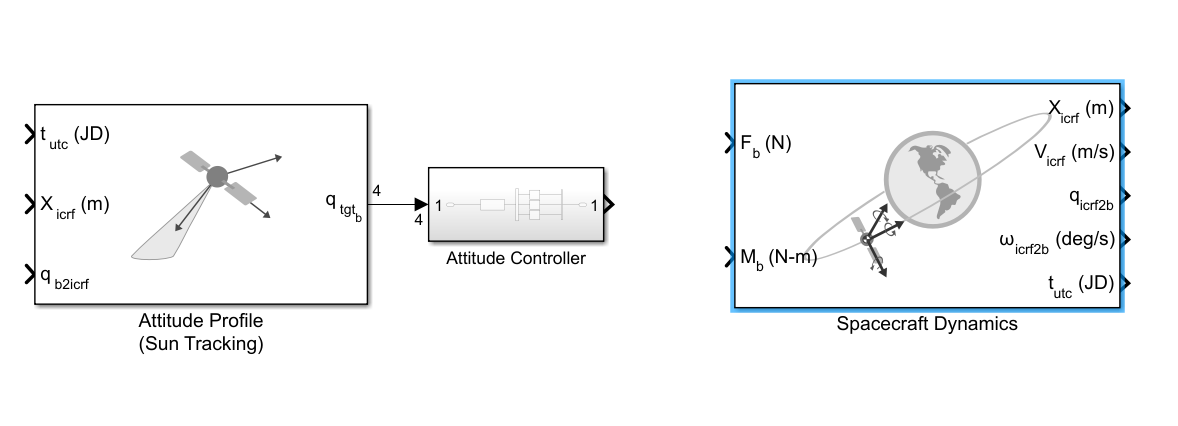

Double-click the block to open its dialog box. Navigate to the "Main" tab. 

Since we are only considering the moments required to control the spacecraft's attitude, clear "Input body forces" and select "Input body moments".

This exercise uses the orbit parameters defined in the previous example (also defined at the top of this script). Enter the mission start time in "Start date/time (UTC Julian date)". Note the format of the date and time.

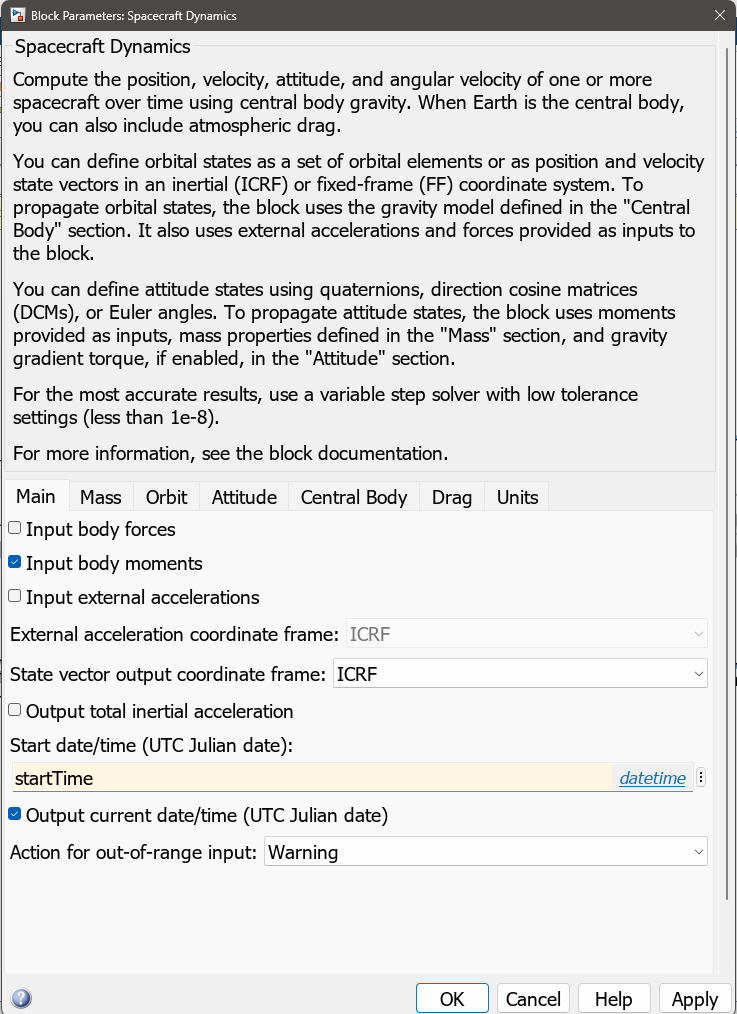

Now, navigate to the "Mass" tab. For this exercise, we assume a spacecraft with a fixed mass 1.0 kg and an inertia tensor of a 3-by-3 identity matrix. Change the settings in the "Mass" tab to reflect these.

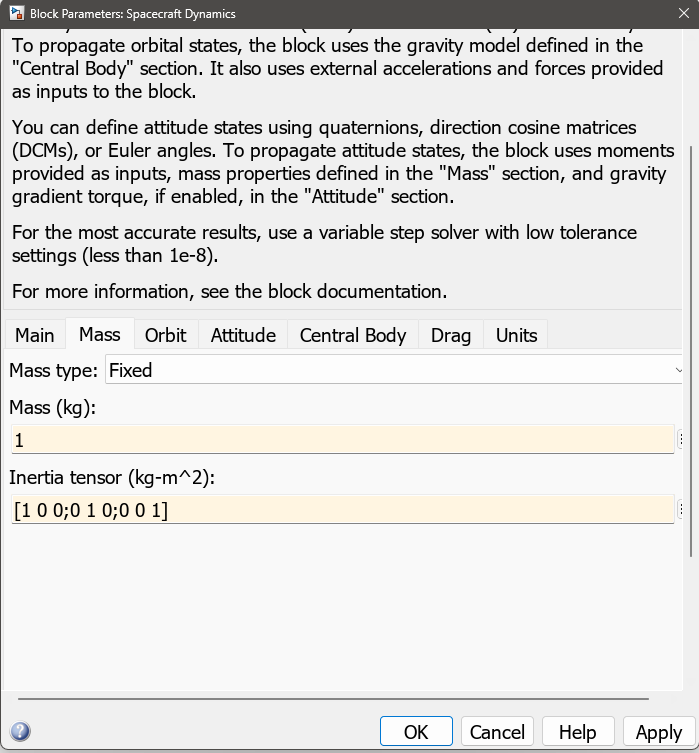

Navigate to the "Orbit" tab. We use orbit parameters from the orbit defined in the previous exercise. Recall that we defined the orbit in terms of Keplerian elements. Therefore, set "Initial state format" to "Orbital elements" and "Orbit type" to "Keplerian". Then, input the variables that store each parameter.

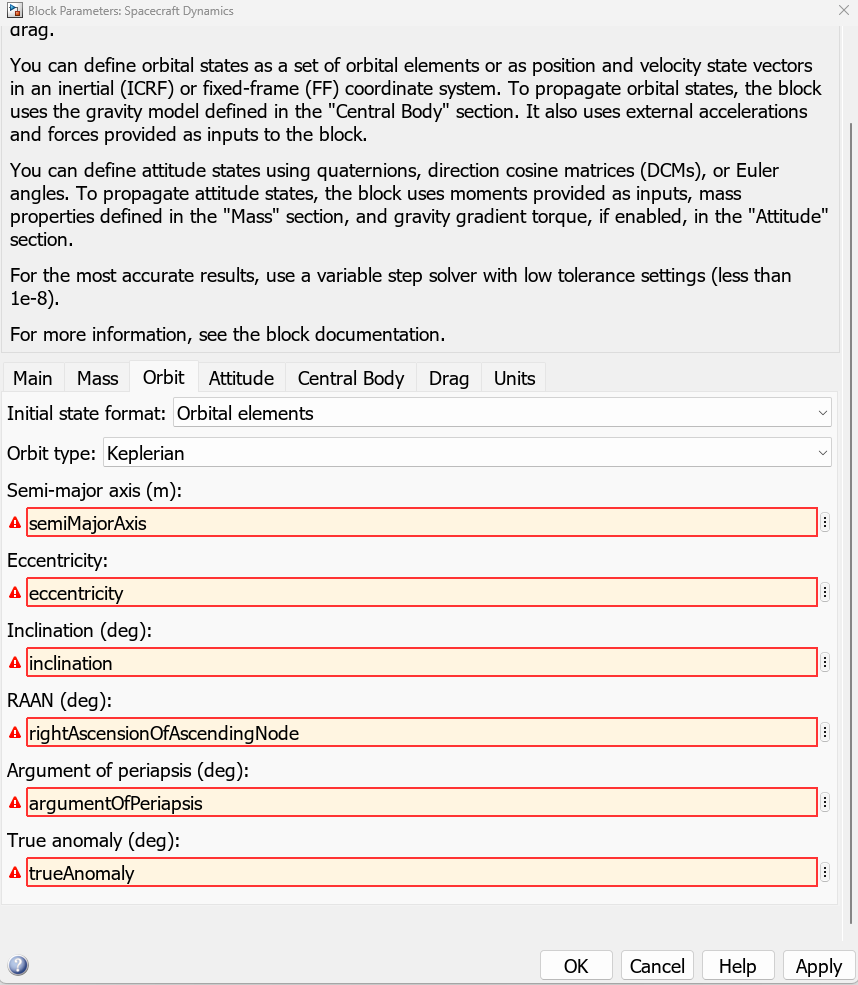

Click "OK". Do not change the parameters in any other tabs. Click back to the top level diagram.

Connect the output of the "Attitude Controller" subsystem to the input port "Mb" (representing moments) of the "Spacecraft Dynamics" block.

Feed the "X icrf" (representing the spacecraft's positions in the International Celestial Reference Frame) output port of the "Spacecraft Dynamics" block to the corresponding input port of the "Attitude Profile (Sun Tracking)" block. Do the same with the "t utc" output port (Universal Coordinated Time) of the "Spacecraft Dynamics" block and the corresponding input port of the "Attitude Profiler (Sun Tracking)" block.

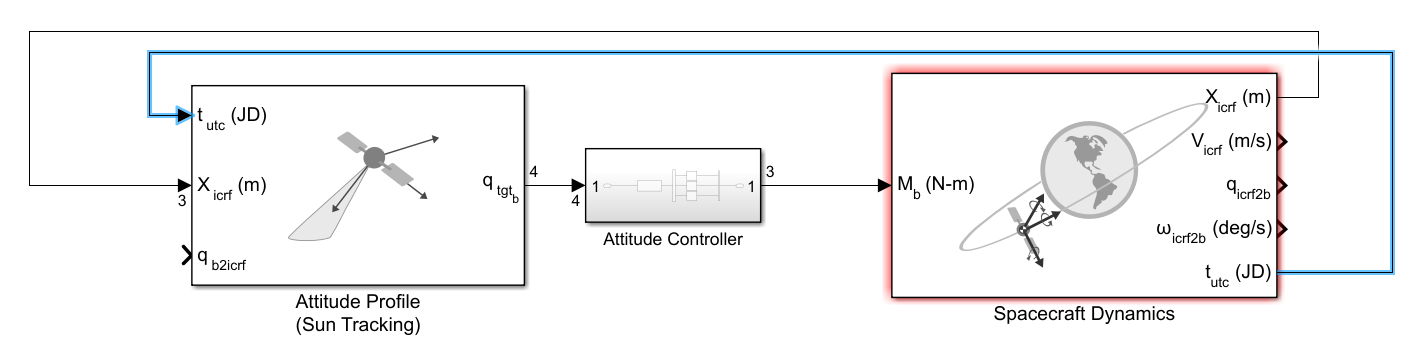

Note the quaternion output of the "Spacecraft Dynamics" block. This output represents the quaternion conveying the rotation from the ICRF to the body frame. Also note that the quaternion input of the "Attitude Profile (Sun Tracking)" block expects the quaternion denoting the rotation from the body frame to the ICRF. 

To resolve this mismatch, use the "Quaternion Conjugate" block to convert the quaternion output of the Spacecraft Dynamics block to the quaternion required by the "Attitude Profile (Sun Tracking)" block.

Then, connect the output of the "Quaternion Conjugate" block to the input port of the "Attitude Profile (Sun Tracking)" block.

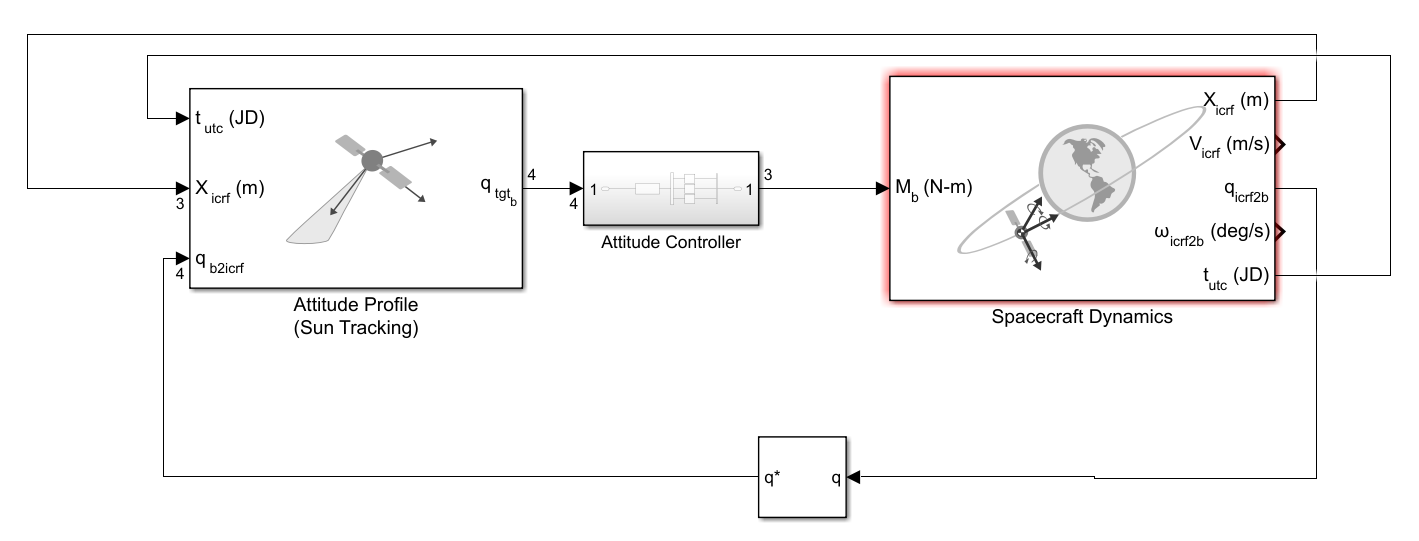

For this exercise, we want to log the time, the spacecraft's positions, velocities, and attitude data. Connect these output ports to their respective "To Workspace" blocks in the specified model. The angular velocity output of the "Spacecraft Dynamics" block is not used, so connect this output port to a "Terminator" block.

Run the model using this command:

sim("Work_Exercise3_SimulinkModel.slx");

Note that three new variables appear in the MATLAB Workspace. 

## Visualize the Orbit in Satellite Scenario

We now visualize the orbit of the spacecraft using a Satellite Scenario viewer.

% prepare data for visualization in Satellite Scenario
% Do not change this code
calDays = datetime(timeData, 'convertfrom','juliandate',...
    'Format','dd-MMM-yyyy G HH:mm:ss');
positionTT = timetable(calDays, positionData);
velocityTT = timetable(calDays, velocityData);


Define the satellite scenario and create the viewer:

% define the scenario
startTime = datetime(2020,8,19,20,55,0); % 19 August 2020 8:55 PM UTC
stopTime = startTime + days(1);          % 20 August 2020 8:55 PM UTC
sampleTime = 60;  

% Launch the satellite scenario. Use the "satelliteScenario" command.
% Hint: To learn more about this command, type "doc satelliteScenario" in
% the command window.
%[ ADD CODE ]


% Create the viewer. Use the "satelliteScenarioViewer" command.
% Hint: To learn more about this command, type "doc
% satelliteScenarioViewer" in the command window.
%[ ADD CODE ]


The position and velocity data for the spacecraft are stored as timetables. To define the satellite within the scenario, use the "satellite" function. Use the name-value argument "CoordinateFrame" to specify that the provided positions and velocities are in the Inertial frame.

Hint: For more information on how to input timetables to the satellite function and the "CoordinateFrame" name-value argument, see the "satellite" function documentation.

% Define the satellite using the "satellite" command.
%[ ADD CODE ]

% Convert the quaternion history from a time series to a time table
% Do not change this code.
quatTT = timeseries2timetable(quatData);


To point the satellite according to the attitudes contained in the timetable "quatTT", use the "pointAt" function.

Hint: For more information about the "pointAt" function, type "doc pointAt".

% Point the satellite according to the attitudes contained in the "quatTT"
% timetable.
%[ ADD CODE ]


To display the body axes of the spacecraft, use the "coordinateAxes" function.

Hint: For more information about the "coordinateAxes" function, type "doc coordinateAxes".

% Display the body axes of the spacecraft
%[ ADD CODE ]


% Play the scenario
play(sc,PlaybackSpeedMultiplier=1000);